# DAAP HW1

*Alberto Doimo*

*Paolo Ostan*

## **Talking Instrument creation **

### **Parameters initialization**

clc; close all; clear all;

instr_name = "piano.wav";
speech_name = "speech.wav";
talking_instr_res_name = "talking_instr_res.wav";

### First test with verbose parameters to check functioning of the script

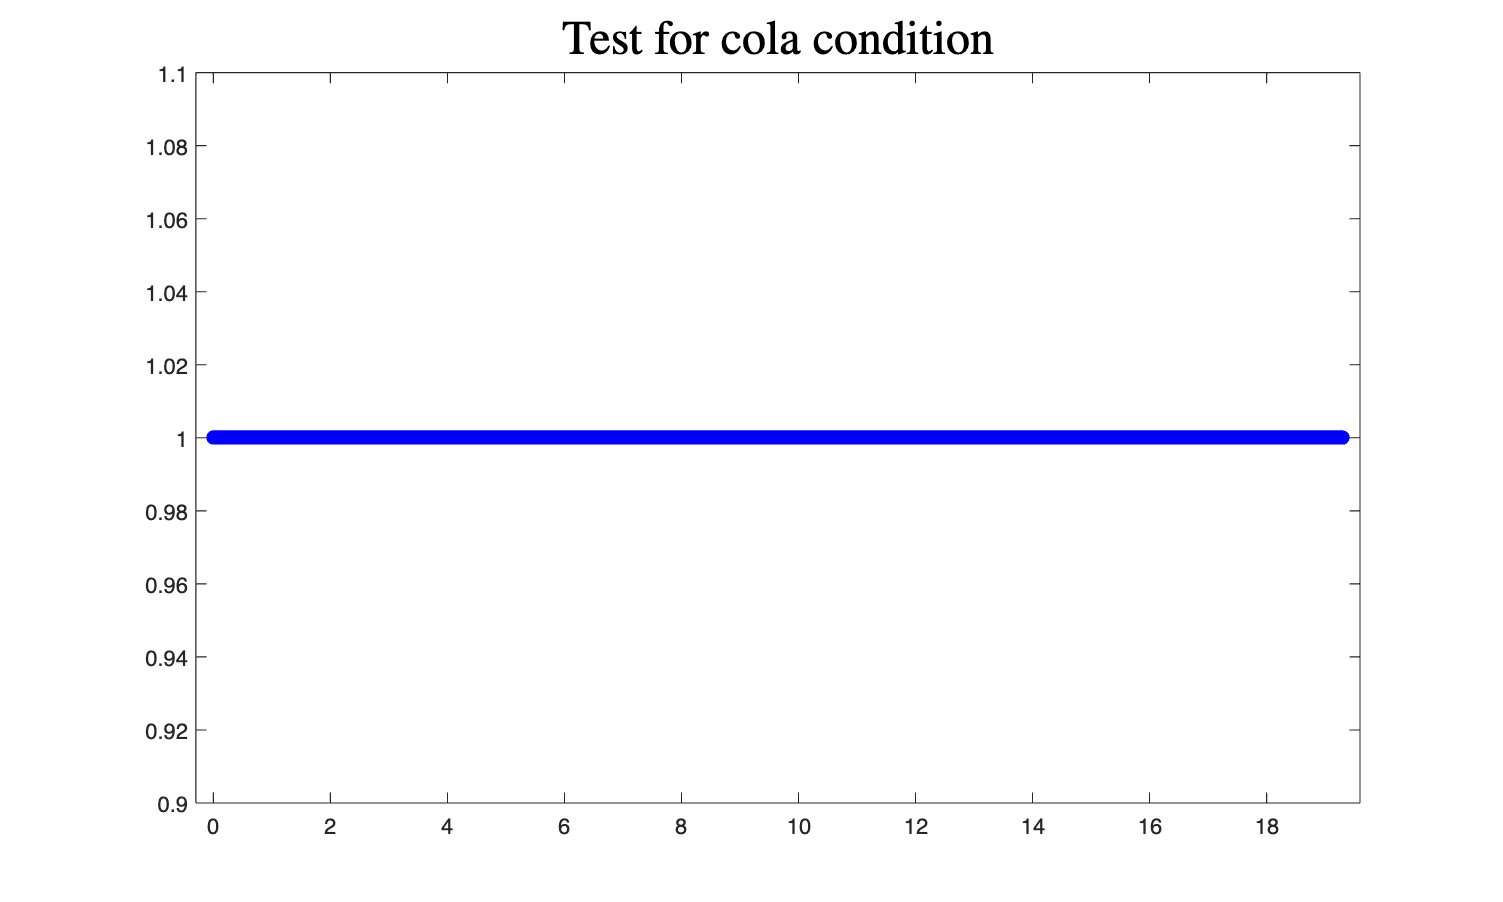

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25

    26

    27

    28

    29

    30

    31

    32

    33

    34

    35

    36

    37

    38

    39

    40

    41

    42

    43

    44

    45

    46

    47

    48

    49

    50

    51

    52

    53

    54

    55

    56

    57

    58

    59

    60

    61

    62

    63

    64

    65

    66

    67

    68

    69

    70

    71

    72

    73

    74

    75

    76

    77

    78

    79

    80

    81

    82

    83

    84

    85

    86

    87

    88

    89

    90

    91

    92

    93

    94

    95

    96

    97

    98

    99

   100

   101

   102

   103

   104

   105

   106

   107

   108

   109

   110

   111

   112

   113

   114

   115

   116

   117

   118

   119

   120

   121

   122

   123

   124

   125



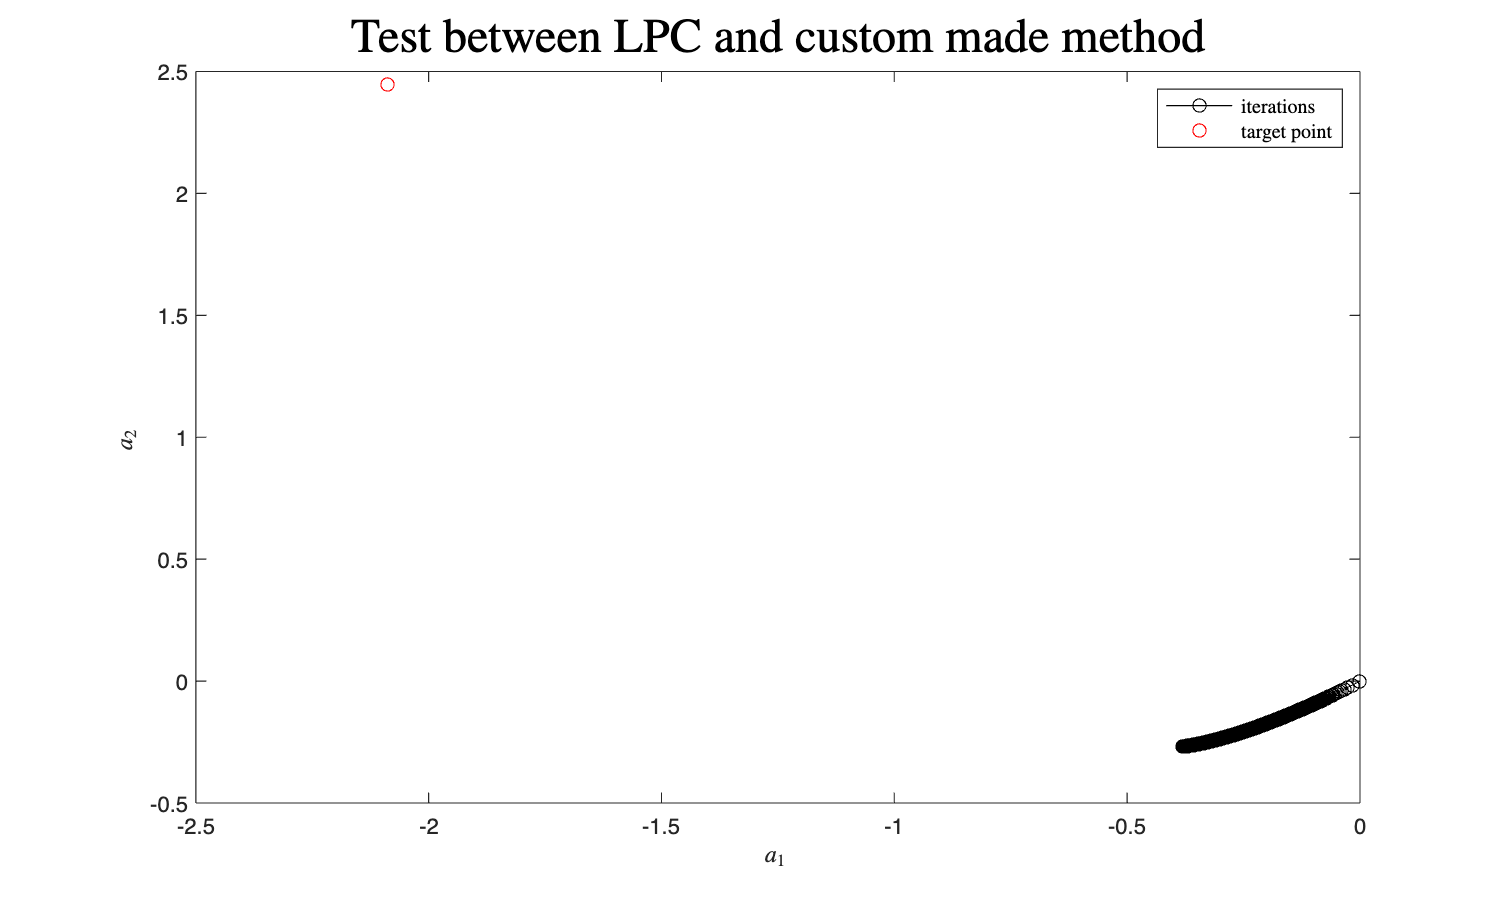

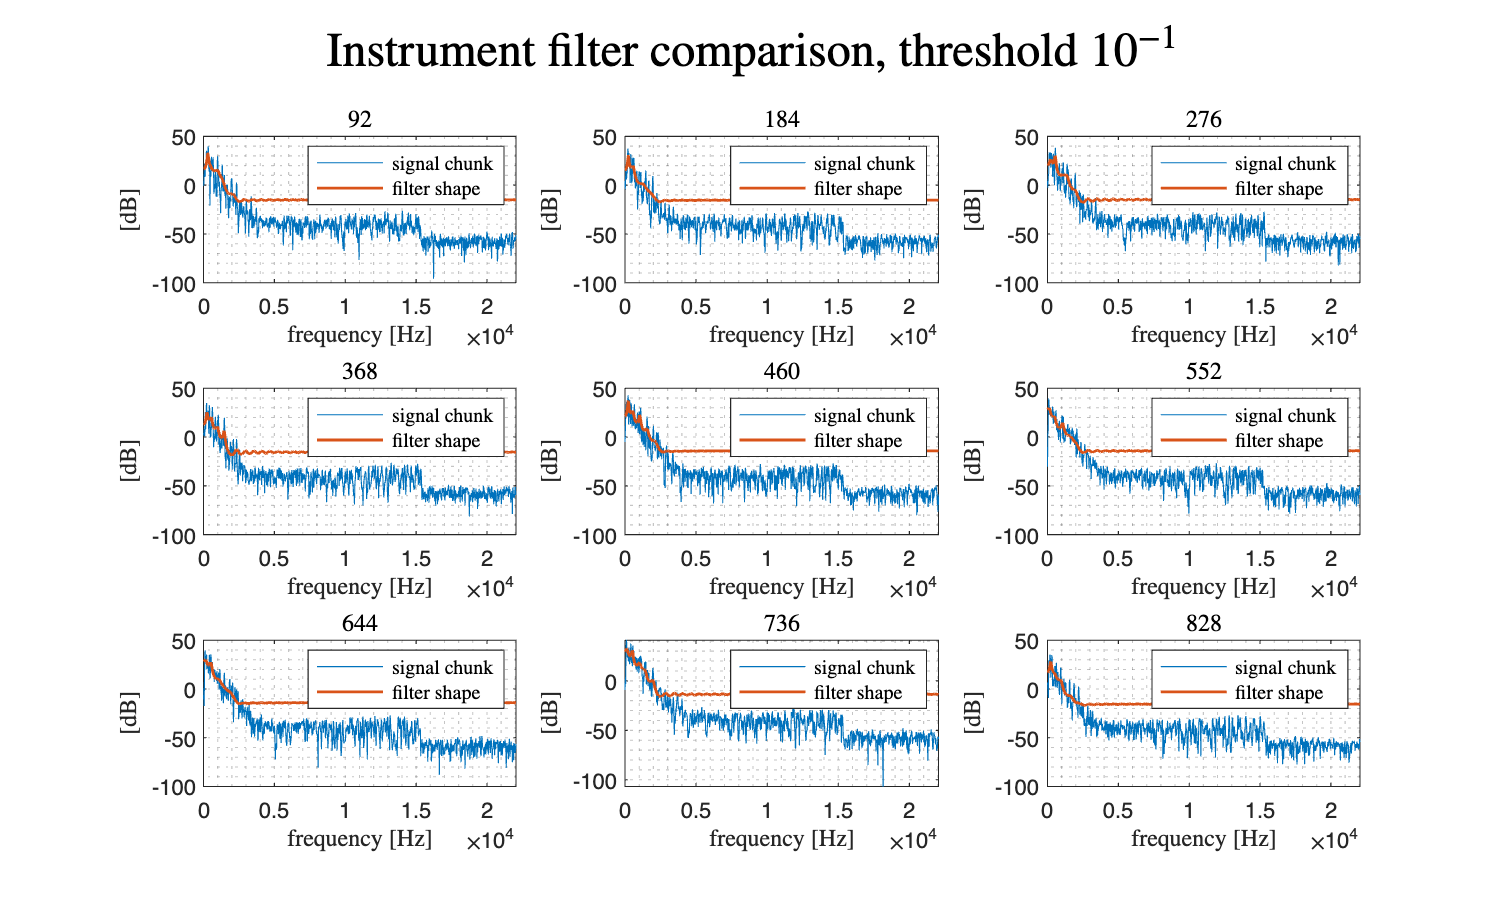

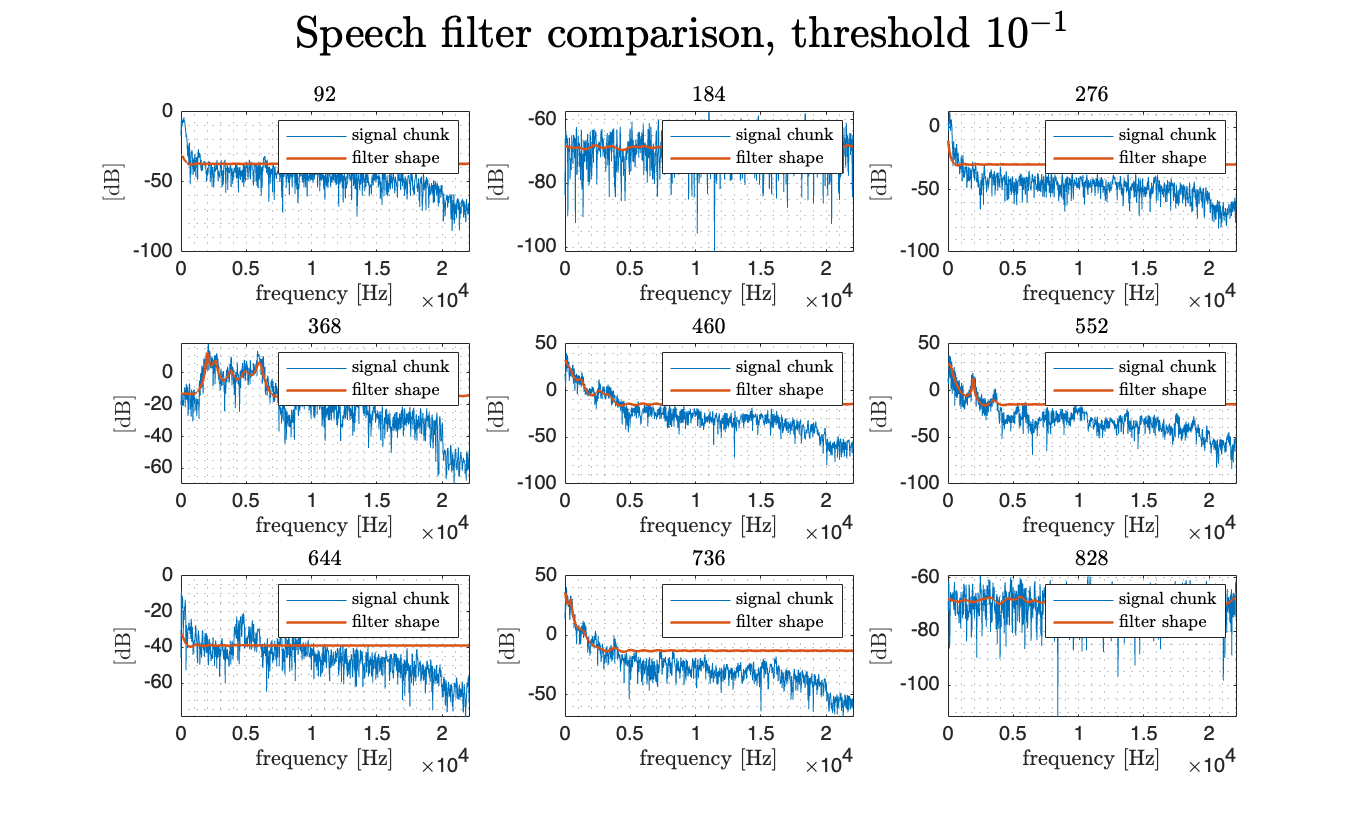

close all;

tic
talking_instr_res_name = "talking_instr_verb.wav";
main(instr_name, speech_name, talking_instr_res_name,"steepDesc",0.3,10^-1,100000,"zeros",0,0,1,"threshold $10^{-1}$");

toc

Elapsed time is 70.005777 seconds.


## test for various threshold values using steepest descent

close all;clc;
disp("threshold 10^-1")
tic
talking_instr_res_name = "talking_instr_10_1.wav";
main(instr_name, speech_name, talking_instr_res_name,"mixed1",0.3,10^-1,100000,"zeros",1,0,0,"threshold $10^{-1}$");
toc
disp("threshold 10^-2")
tic
talking_instr_res_name = "talking_instr_10_2.wav";
main(instr_name, speech_name, talking_instr_res_name,"mixed1",0.3,10^-2,100000,"zeros",1,0,0,"threshold $10^{-2}$");
toc
disp("threshold 10^-4")

tic
talking_instr_res_name = "talking_instr_10_4.wav";
main(instr_name, speech_name, talking_instr_res_name,"mixed1",0.3,10^-4,100000,"zeros",1,0,0,"threshold $10^{-4}$");
toc

## test for various coefficients initialization values using steepest descent

disp("time for speech steepest descent equals to previous value")

tic
talking_instr_res_name = "talking_instr_zeros.wav";
main(instr_name, speech_name, talking_instr_res_name,"mixed1",0.3,0.5*10^-1,100000,"prev",1,0,0,"prev");
toc
disp("time for speech steepest descent equals to zero")


tic
talking_instr_res_name = "talking_instr_zeros.wav";
main(instr_name, speech_name, talking_instr_res_name,"mixed1",0.3,0.5*10^-1,100000,"zeros",1,0,0,"zeros");
toc
disp("time for speech steepest descent equals to one")

tic

talking_instr_res_name = "talking_instr_ones.wav";
main(instr_name, speech_name, talking_instr_res_name,"mixed1",0.3,0.5*10^-1,100000,"ones",1,0,0,"ones");
toc

disp("time for speech steepest descent equals to random values")


tic
talking_instr_res_name = "talking_instr_randn.wav";
main(instr_name, speech_name, talking_instr_res_name,"mixed1",0.3,0.5*10^-1,100000,"randn",1,0,0,"prev");
toc

%sound(avviso(1:5*44100),44100);